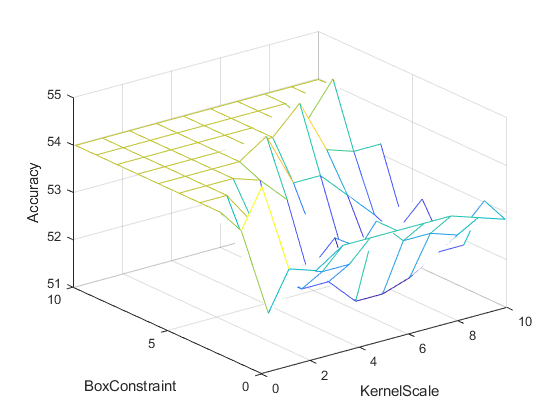

ans = 32×3 table
    Character    Validation_Accuracy    Testing_Accuracy
    _________    ___________________    ________________

      {'2'}            57.773                  50       
      {'3'}            57.588                  50       
      {'4'}            59.072                  50       
      {'5'}            66.346                  50       
      {'6'}            71.739                  50       
      {'7'}            62.984                  50       
      {'8'}            60.504                  50       
      {'9'}             57.17                  50       
      {'A'}            53.598                  50       
      {'B'}            65.487                  50       
      {'C'}            66.292                  50       
      {'D'}            54.661                  50       
      {'E'}            61.694                  50       
      {'F'}            61

ans = 6.2500

clear all;
if ~isfile('S_net.mat')
    if ~isfile('features_labels.mat')
        load('character_info_SVM.mat')
        N = size(char_imgs,2);
        features = zeros(N,72);
        labels = cell2mat(char_labels);
        for i=1:N
            features(i,:) = extractHOGFeatures(char_imgs{i});
        end
        rng(22);
        idx = randperm(N);
        
        idx_train = idx(1:N*.6);
        idx_val = idx(N*.6:N*.8);
        idx_test = idx(N*.8:N);
        
        features_train = features(idx_train,:);
        features_val = features(idx_val,:);
        features_test = features(idx_test,:);
        
        labels_train = labels(idx_train);
        labels_val = labels(idx_val);
        labels_test = labels(idx_test);
        
        save('features_labels.mat', 'features_train','features_val','features_test','labels_train','labels_val','labels_test')
    else
        load('features_labels.mat')
    end
    
    char_ls = unique(labels_train);
    N = size(char_ls,2);
    chars = {};
    val_accs = zeros(N,1);
    test_accs = zeros(N,1);
 
    c = 'A';
    
    p = 10;
    x = linspace(0.1,10,p);
    y = linspace(0.1,10,p);
    z = zeros(p);
    
    best_acc = 0;
    best_ks = 0;
    best_bc = 0;
    
    target_train = zeros(sum(labels_train == c)*2, 1);
    target_train(1:sum(labels_train == c)) = find(labels_train == c);
    id_not = find(labels_train ~= c);
    target_train(sum(labels_train == c)+1:sum(labels_train == c)*2) = id_not(1:sum(labels_train == c));
    features_train_t = features_train(target_train);
    labels_train_t = labels_train(target_train);
    
    target_val = zeros(sum(labels_val == c)*2, 1);
    target_val(1:sum(labels_val == c)) = find(labels_val == c);
    id_not = find(labels_val ~= c);
    target_val(sum(labels_val == c)+1:sum(labels_val == c)*2) = id_not(1:sum(labels_val == c));
    features_val_t = features_val(target_val);
    labels_val_t = labels_val(target_val);
    
    target_test = zeros(sum(labels_test == c)*2, 1);
    target_test(1:sum(labels_test == c)) = find(labels_test == c);
    id_not = find(labels_test ~= c);
    target_test(sum(labels_test == c)+1:sum(labels_test == c)*2) = id_not(1:sum(labels_test == c));
    features_test_t = features_test(target_test);
    labels_test_t = labels_test(target_test);
       
    target_train = ((labels_train_t==c).*2)-1;
    target_val = ((labels_val_t==c).*2)-1;
    target_test = ((labels_test_t==c).*2)-1;
    count_char = sum(labels_train_t==c);
    
    for i = 1:p
        for j = 1:p
            net = fitcsvm(features_train_t,target_train,'KernelFunction','RBF', 'Standardize',false, ...
            'ClassNames',[-1, 1], 'KernelScale', x(i), 'BoxConstraint', y(j));
            [detectedClasses, distances] = predict(net, features_val_t);
            truePos_trueNeg = sum((target_val + detectedClasses.') == 2) + sum((target_val + detectedClasses.') == -2);
            z(i,j) = truePos_trueNeg/size(target_val,2)*100;
            if z(i,j) >= best_acc
                best_acc = z(i,j);
                best_ks = x(i);
                best_bc = y(j);
            end
        end
    end

    nets = cell(N,1);
    for i=1:N
        c = char_ls(i);
        chars = [chars,c];
        
        target_train = zeros(sum(labels_train == c)*2, 1);
        target_train(1:sum(labels_train == c)) = find(labels_train == c);
        id_not = find(labels_train ~= c);
        target_train(sum(labels_train == c)+1:sum(labels_train == c)*2) = id_not(1:sum(labels_train == c));
        features_train_t = features_train(target_train);
        labels_train_t = labels_train(target_train);
        
        target_val = zeros(sum(labels_val == c)*2, 1);
        target_val(1:sum(labels_val == c)) = find(labels_val == c);
        id_not = find(labels_val ~= c);
        target_val(sum(labels_val == c)+1:sum(labels_val == c)*2) = id_not(1:sum(labels_val == c));
        features_val_t = features_val(target_val);
        labels_val_t = labels_val(target_val);
        
        target_test = zeros(sum(labels_test == c)*2, 1);
        target_test(1:sum(labels_test == c)) = find(labels_test == c);
        id_not = find(labels_test ~= c);
        target_test(sum(labels_test == c)+1:sum(labels_test == c)*2) = id_not(1:sum(labels_test == c));
        features_test_t = features_test(target_test);
        labels_test_t = labels_test(target_test);
        
        % Convert Boolean Arrays to -1 / +1 for SVM
        target_train = ((labels_train_t==c).*2)-1;
        target_val = ((labels_val_t==c).*2)-1;
        target_test = ((labels_test_t==c).*2)-1;
        
        
        testing = find(target_train == -1);
        
        net = fitcsvm(features_train_t,target_train,'KernelFunction','RBF', 'Standardize',true, ...
        'ClassNames',[-1, 1], 'KernelScale', 1.2, 'BoxConstraint', 1.2);
        [detectedClasses, distances] = predict(net, features_val_t);
        truePos_trueNeg = sum((target_val + detectedClasses.') == 2) + sum((target_val + detectedClasses.') == -2);
        val_acc = truePos_trueNeg/size(target_val,2)*100;
    
        %fprintf("Validation Accuracy for %s-SVM: %.3f\n", c, val_acc);
        
        [detectedClasses, distances] = predict(net, features_test_t);
        true_pos = sum(target_test+detectedClasses==2);
        false_neg = sum((target_test == 1).*(detectedClasses == -1));
        false_pos = sum((target_test == -1).*(detectedClasses == 1));
        true_neg = sum(target_test+detectedClasses==-2);
        total = true_pos + false_pos + false_neg + true_neg;
        test_acc = (true_pos + true_neg)/total*100;
        
        %fprintf("Testing Accuracy for %s-SVM: %.3f\n\n", c, test_acc);
        val_accs(i) = val_acc;
        test_accs(i) = test_acc;
        
        nets{i} = net;
    end
    
    figure;
    mesh(x,y,z);
    xlabel('KernelScale');
    ylabel('BoxConstraint');
    zlabel('Accuracy');
    
    Character = chars.';
    Validation_Accuracy = val_accs;
    Testing_Accuracy = test_accs;
    table(Character,Validation_Accuracy,Testing_Accuracy)
    
    m=sum(test_accs)/32;
    ((m/100)^4)*100
  
    save('SVM_net.mat', 'nets', 'chars')
else
    load('SVM_net.mat')
end